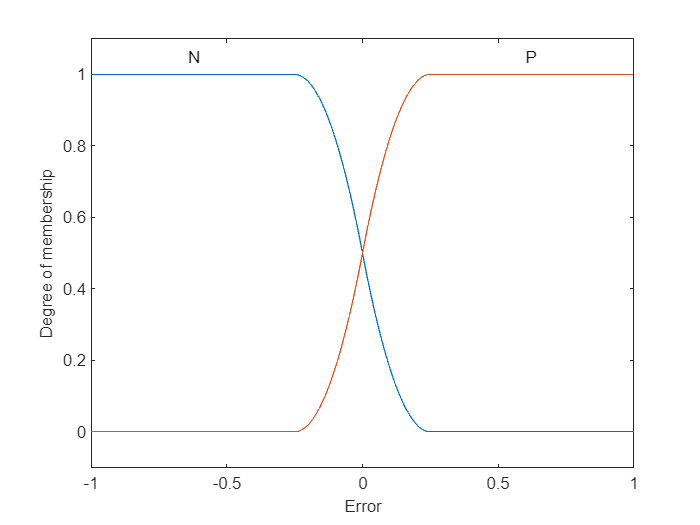

% Create a Fuzzy Inference System (FIS)
bbFIS = mamfis( ...
    'Name', 'Fuzzy Buck-Boost', ...
    'NumInputs', 2, 'NumInputMFs', 2, ...
    'NumOutputs', 1, 'NumOutputMFS', 2, ...
    'AddRule', 'none');

% Inputs
bbFIS.Inputs(1).Name = 'Error';
bbFIS.Inputs(1).Range = [-1 1];
bbFIS.Inputs(1).MembershipFunctions(1).Name = 'N';
bbFIS.Inputs(1).MembershipFunctions(1).Type = 'zmf';
bbFIS.Inputs(1).MembershipFunctions(1).Parameters = [-0.25 0.25];
bbFIS.Inputs(1).MembershipFunctions(2).Name = 'P';
bbFIS.Inputs(1).MembershipFunctions(2).Type = 'smf';
bbFIS.Inputs(1).MembershipFunctions(2).Parameters = [-0.25 0.25];

plotmf(bbFIS, 'input', 1, 1000);

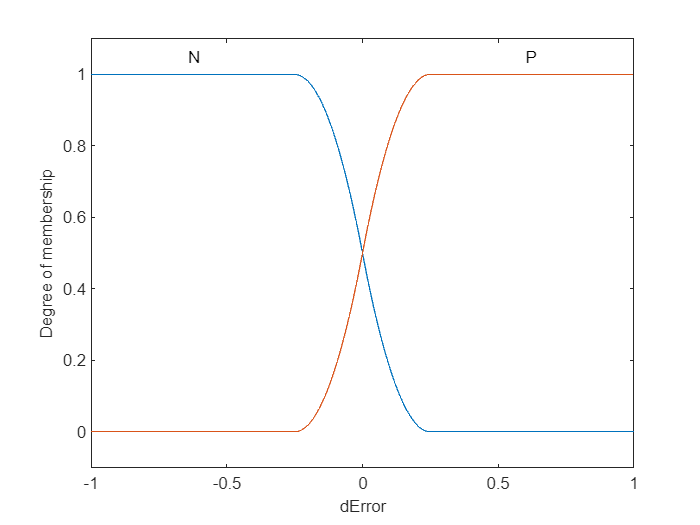


bbFIS.Inputs(2).Name = 'dError';
bbFIS.Inputs(2).Range = [-1 1];
bbFIS.Inputs(2).MembershipFunctions(1).Name = 'N';
bbFIS.Inputs(2).MembershipFunctions(1).Type = 'zmf';
bbFIS.Inputs(2).MembershipFunctions(1).Parameters = [-0.25 0.25];
bbFIS.Inputs(2).MembershipFunctions(2).Name = 'P';
bbFIS.Inputs(2).MembershipFunctions(2).Type = 'smf';
bbFIS.Inputs(2).MembershipFunctions(2).Parameters = [-0.25 0.25];
plotmf(bbFIS, 'input', 2, 1000);

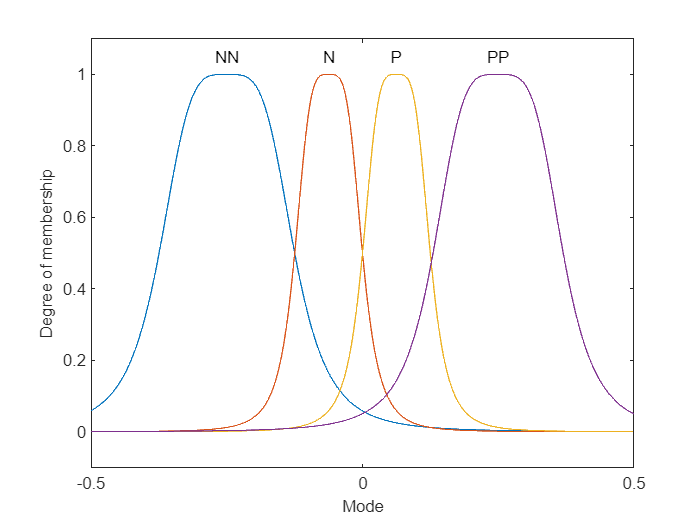


% Outputs
bbFIS.Outputs(1).Name = 'Mode';
bbFIS.Outputs(1).Range = [-0.5 0.5];
bbFIS.Outputs(1).MembershipFunctions(1).Name = 'NN';
bbFIS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf';
bbFIS.Outputs(1).MembershipFunctions(1).Parameters = [0.125 2 -0.25];
bbFIS.Outputs(1).MembershipFunctions(2).Name = 'N';
bbFIS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf';
bbFIS.Outputs(1).MembershipFunctions(2).Parameters = [0.0625 2 -0.0625];
bbFIS.Outputs(1).MembershipFunctions(3).Name = 'P';
bbFIS.Outputs(1).MembershipFunctions(3).Type = 'gbellmf';
bbFIS.Outputs(1).MembershipFunctions(3).Parameters = [0.0625 2 0.0625];
bbFIS.Outputs(1).MembershipFunctions(4).Name = 'PP';
bbFIS.Outputs(1).MembershipFunctions(4).Type = 'gbellmf';
bbFIS.Outputs(1).MembershipFunctions(4).Parameters = [0.12 2 0.25];

plotmf(bbFIS, 'output', 1, 1000);

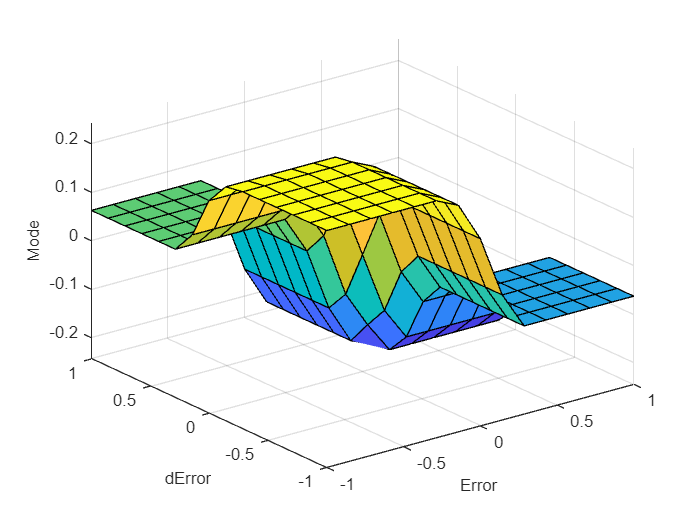


% Specify Rules
rules = [
    "If Error is N and dError is N then Mode is PP";
    "If Error is P and dError is N then Mode is N";

    "If Error is N and dError is P then Mode is P";
    "If Error is P and dError is P then Mode is NN";
    ];

bbFIS = addRule(bbFIS, rules);
figure
gensurf(bbFIS)

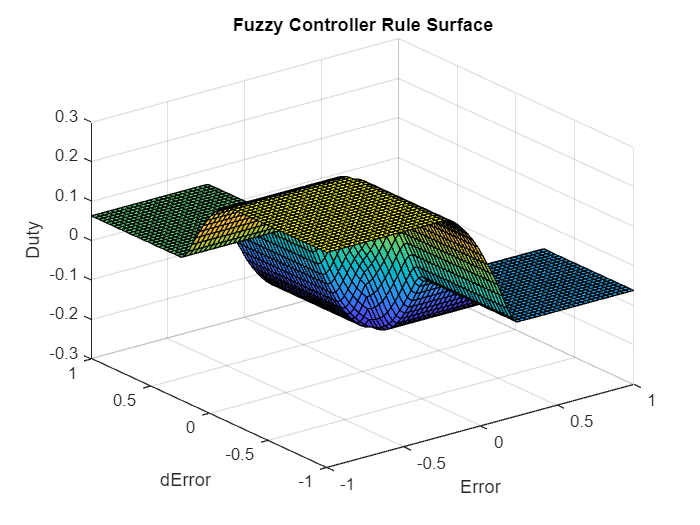

% Define input ranges
n = 64;
Ev = linspace(-1, 1, n);
dEv = linspace(-1, 1, n);

% Create a grid of all
[Error_grid, dError_grid] = meshgrid(Ev, dEv);

% Evaluate FIS for all combinations
inputs = [Error_grid(:), dError_grid(:)];    % Reshape into Nx2 matrix
duty_cycle = evalfis(bbFIS, inputs);         % Compute duty cycle for all inputs

% Reshape output into a 2D matrix
dct = reshape(duty_cycle, [n, n]);

figure
surf(Ev, dEv, dct);
xlabel('Error'); ylabel('dError'); zlabel('Duty');
title('Fuzzy Controller Rule Surface');